Data 

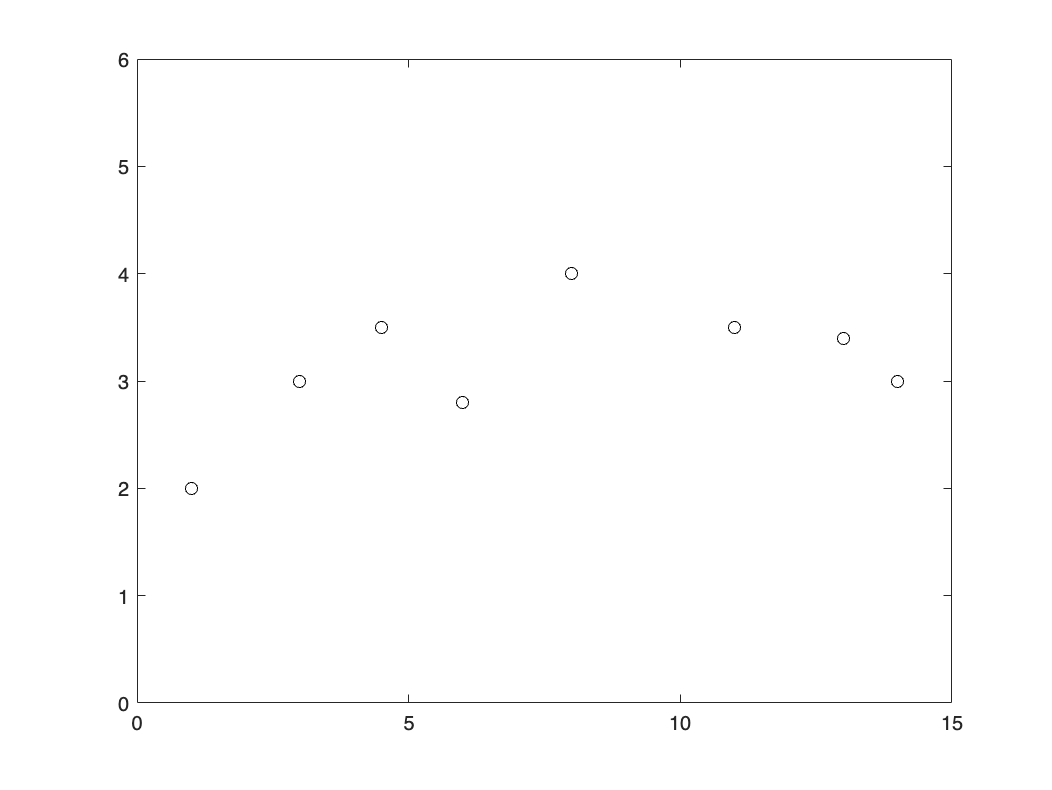

x = [1 3 4.5 6 8 11 13 14];
y = [2 3 3.5 2.8 4 3.5 3.4 3];

figure
plot(x, y, 'kO')
hold on
axis([0 15 0 6])

Linear spline

xx = 1:0.1:14;

yy1 = interp1(x, y, xx, 'linear')

yy1 =     2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500    2.5000    2.5500    2.6000    2.6500    2.7000    2.7500    2.8000    2.8500    2.9000    2.9500    3.0000    3.0333    3.0667    3.1000    3.1333    3.1667    3.2000    3.2333    3.2667    3.3000    3.3333    3.3667    3.4000    3.4333    3.4667    3.5000    3.4533    3.4067    3.3600    3.3133    3.2667    3.2200    3.1733    3.1267    3.0800    3.0333    2.9867    2.9400    2.8933    2.8467


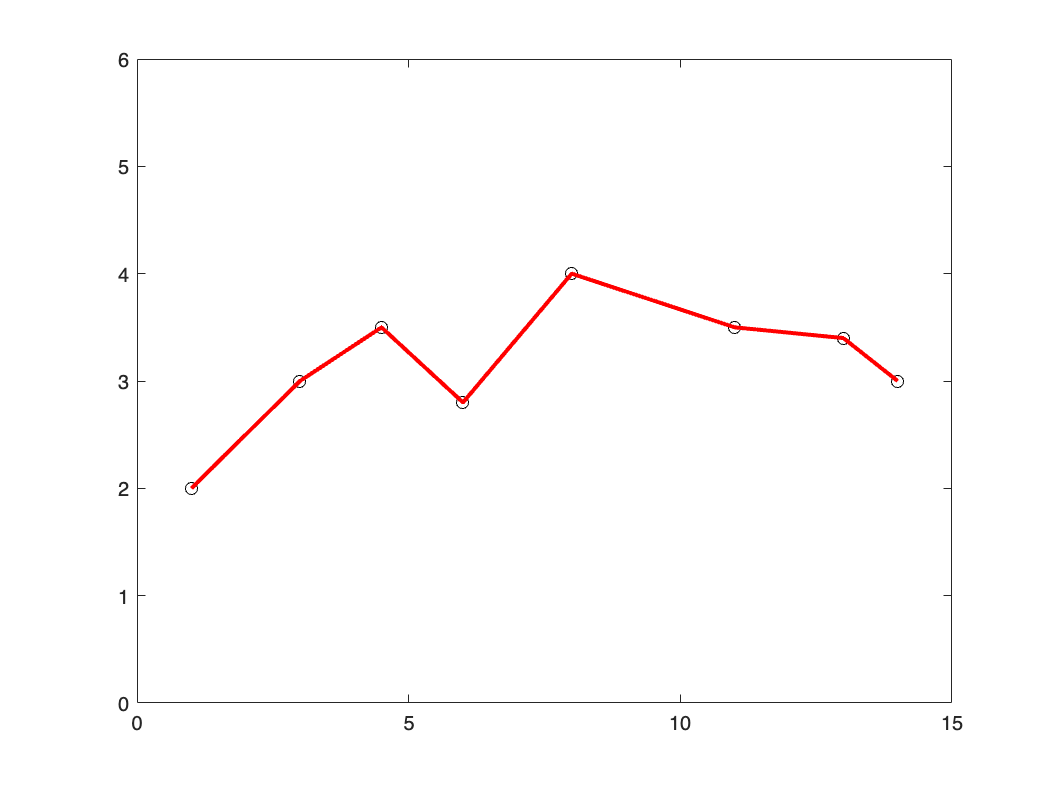


figure
plot(x, y, 'kO')
hold on
plot(xx, yy1, '-r', 'LineWidth', 2)
axis([0 15 0 6])

Quadratic spline

Cubic spline (natural spline)

xx = 1:0.1:14;

yy3 = natspline(x, y, xx)

yy3 =     2.0000    2.0463    2.0927    2.1392    2.1859    2.2328    2.2799    2.3274    2.3753    2.4236    2.4724    2.5218    2.5717    2.6224    2.6737    2.7259    2.7788    2.8326    2.8874    2.9432    3.0000    3.0578    3.1158    3.1732    3.2291    3.2826    3.3330    3.3793    3.4207    3.4563    3.4852    3.5066    3.5197    3.5235    3.5172    3.5000    3.4714    3.4327    3.3856    3.3319    3.2734    3.2117    3.1485    3.0857    3.0249    2.9679    2.9164    2.8721    2.8368    2.8122


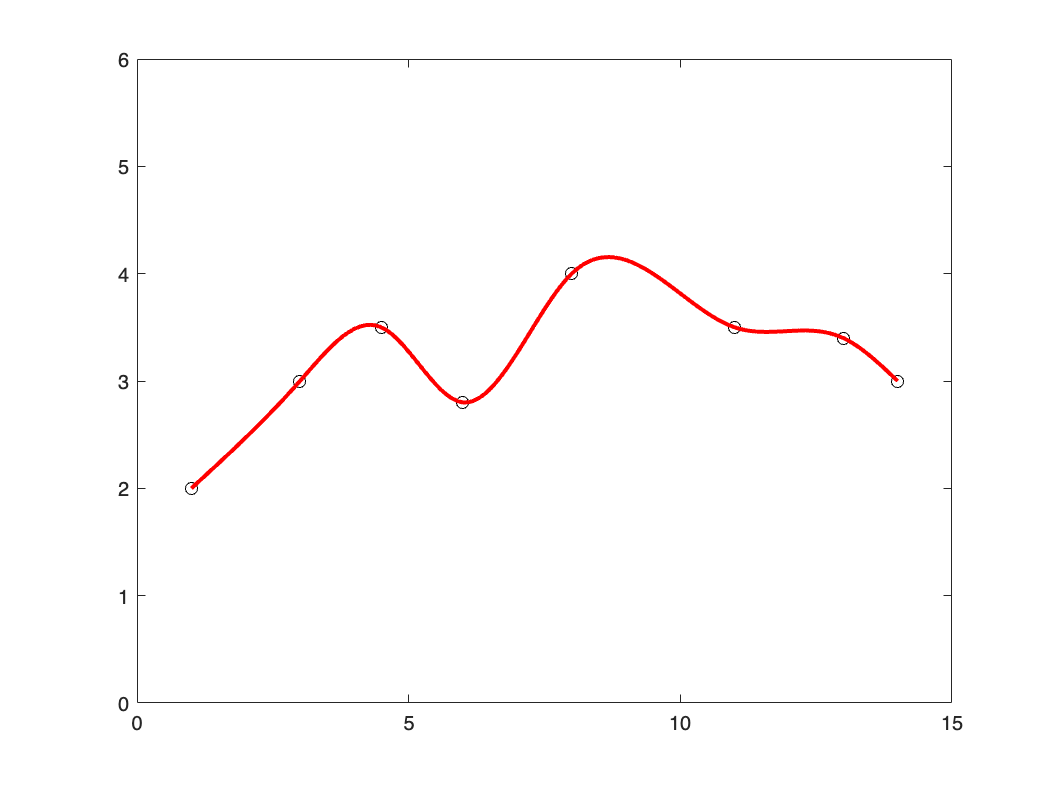


figure
plot(x, y, 'kO')
hold on
plot(xx, yy3, '-r', 'LineWidth', 2)
axis([0 15 0 6])

Cubic spline (using interp1)

xx = 1:0.1:14;

yy3 = interp1(x, y, xx, 'spline')

yy3 =     2.0000    1.9941    1.9978    2.0103    2.0311    2.0597    2.0953    2.1373    2.1853    2.2385    2.2964    2.3584    2.4239    2.4922    2.5628    2.6350    2.7083    2.7821    2.8557    2.9285    3.0000    3.0695    3.1365    3.2003    3.2604    3.3161    3.3668    3.4119    3.4509    3.4830    3.5078    3.5247    3.5329    3.5319    3.5212    3.5000    3.4682    3.4271    3.3783    3.3235    3.2644    3.2026    3.1397    3.0775    3.0177    2.9617    2.9115    2.8685    2.8345    2.8111


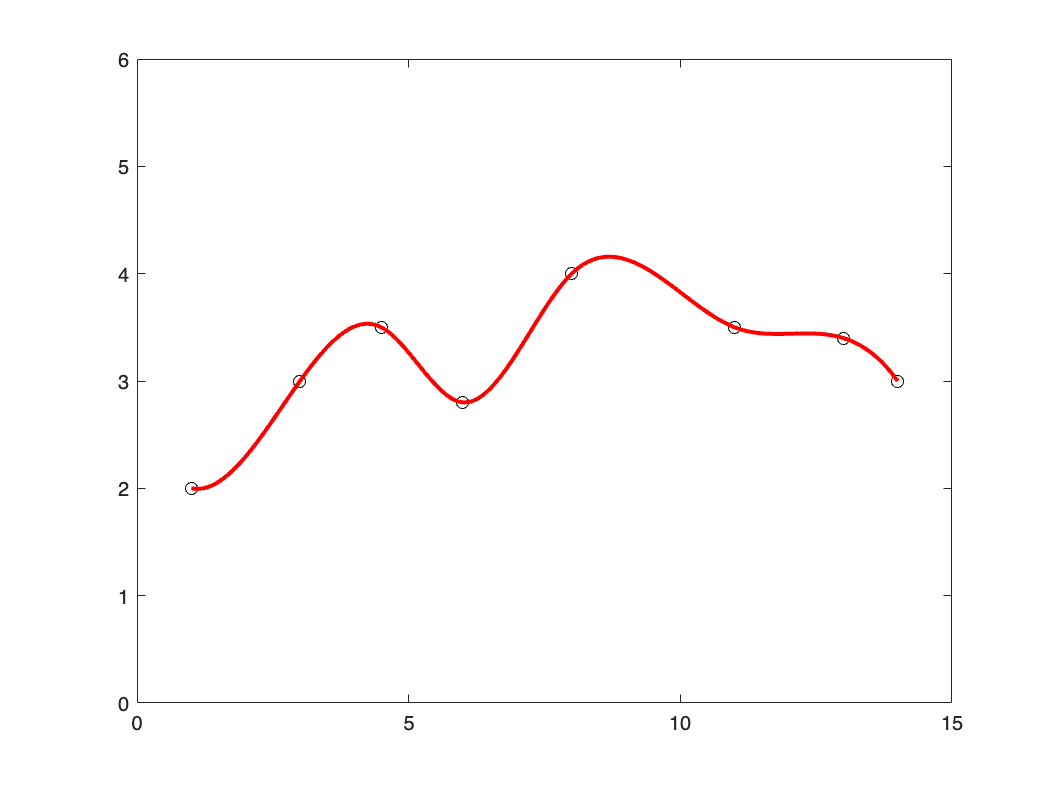


figure
plot(x, y, 'kO')
hold on
plot(xx, yy3, '-r', 'LineWidth', 2)
axis([0 15 0 6])

Cubic spline (using spline)

Cubic spline (using spline & ppval)

xx = 1:0.1:14;

% cs = cubic spline, or we can use pp = piecewise polynomial
cs = spline(x, y)

cs = struct with fields:
      form: 'pp'
    breaks: [1 3 4.5000 6 8 11 13 14]
     coefs: [7×4 double]
    pieces: 7
     order: 4
       dim: 1


yy3 = ppval(cs, xx)

yy3 =     2.0000    1.9941    1.9978    2.0103    2.0311    2.0597    2.0953    2.1373    2.1853    2.2385    2.2964    2.3584    2.4239    2.4922    2.5628    2.6350    2.7083    2.7821    2.8557    2.9285    3.0000    3.0695    3.1365    3.2003    3.2604    3.3161    3.3668    3.4119    3.4509    3.4830    3.5078    3.5247    3.5329    3.5319    3.5212    3.5000    3.4682    3.4271    3.3783    3.3235    3.2644    3.2026    3.1397    3.0775    3.0177    2.9617    2.9115    2.8685    2.8345    2.8111



figure
plot(x, y, 'kO')
hold on
plot(xx, yy3, 'r-', 'LineWidth', 2)
axis([0 15 0 6])

Cubic spline (plot each segment with different colors)

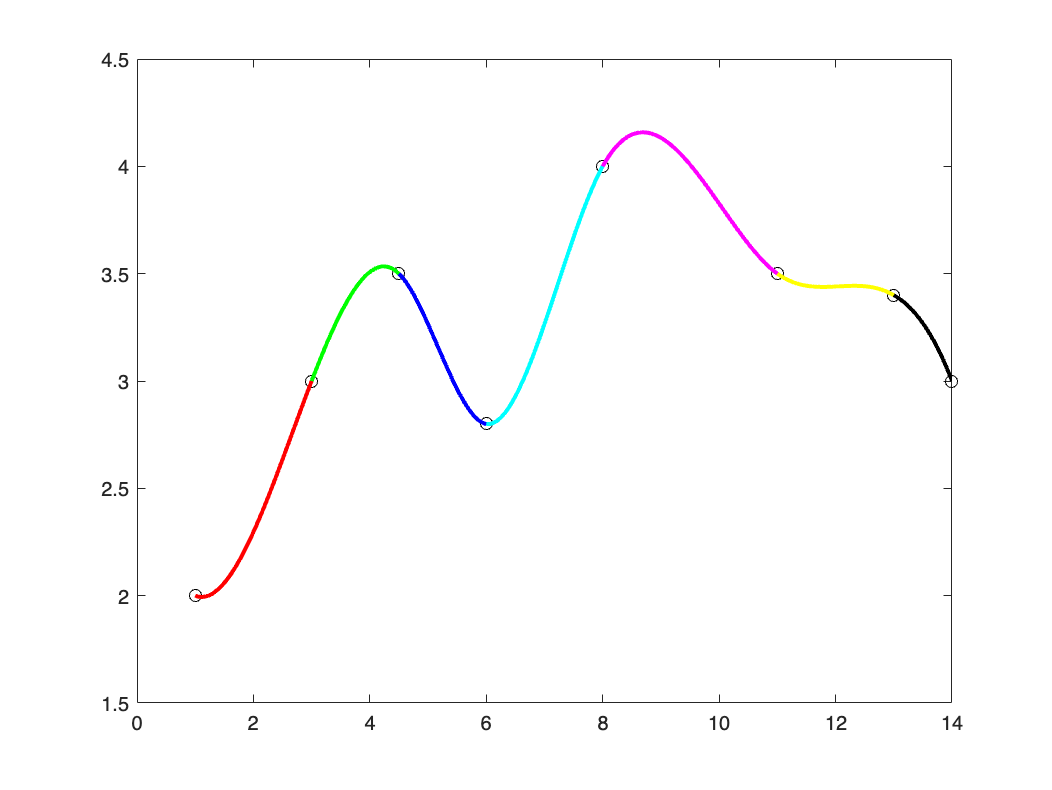

segment1 = linspace(x(1), x(2));
segment2 = linspace(x(2), x(3));
segment3 = linspace(x(3), x(4));
segment4 = linspace(x(4), x(5));
segment5 = linspace(x(5), x(6));
segment6 = linspace(x(6), x(7));
segment7 = linspace(x(7), x(8));

figure
plot(x, y, 'kO')
hold on
plot(segment1, ppval(cs, segment1), 'r-', 'LineWidth',2)
hold on
plot(segment2, ppval(cs, segment2), 'g-', 'LineWidth',2)
hold on
plot(segment3, ppval(cs, segment3), 'b-', 'LineWidth',2)
hold on
plot(segment4, ppval(cs, segment4), 'c-', 'LineWidth',2)
hold on
plot(segment5, ppval(cs, segment5), 'm-', 'LineWidth',2)
hold on
plot(segment6, ppval(cs, segment6), 'y-', 'LineWidth',2)
hold on
plot(segment7, ppval(cs, segment7), 'k-', 'LineWidth',2)
hold on